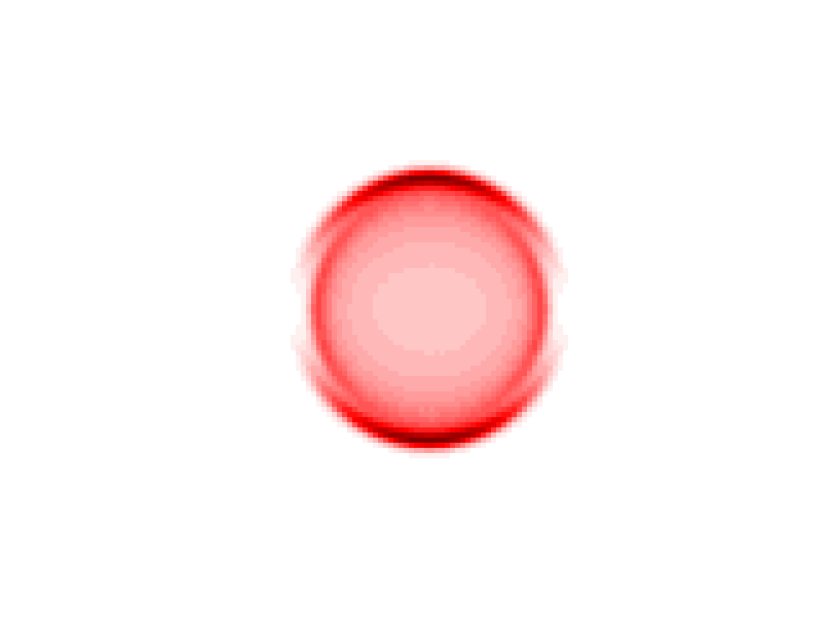

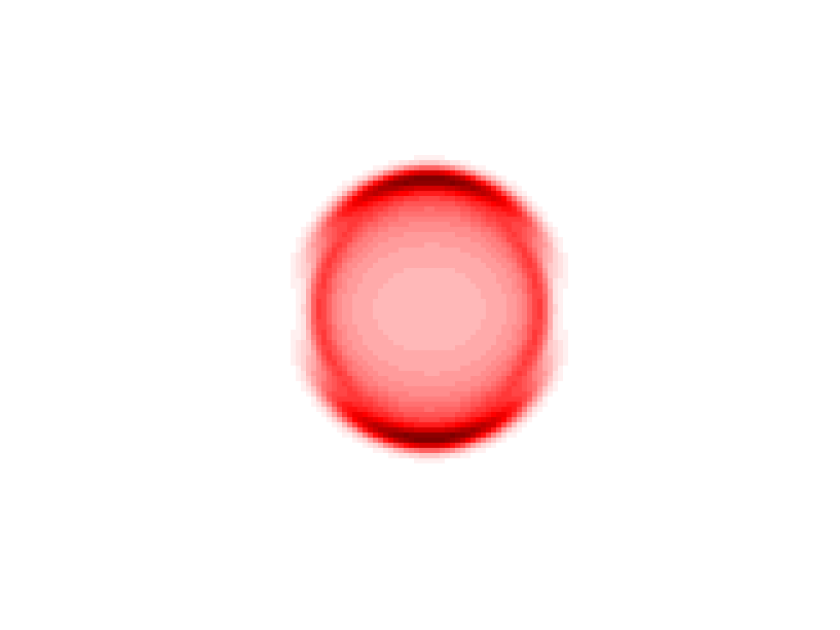

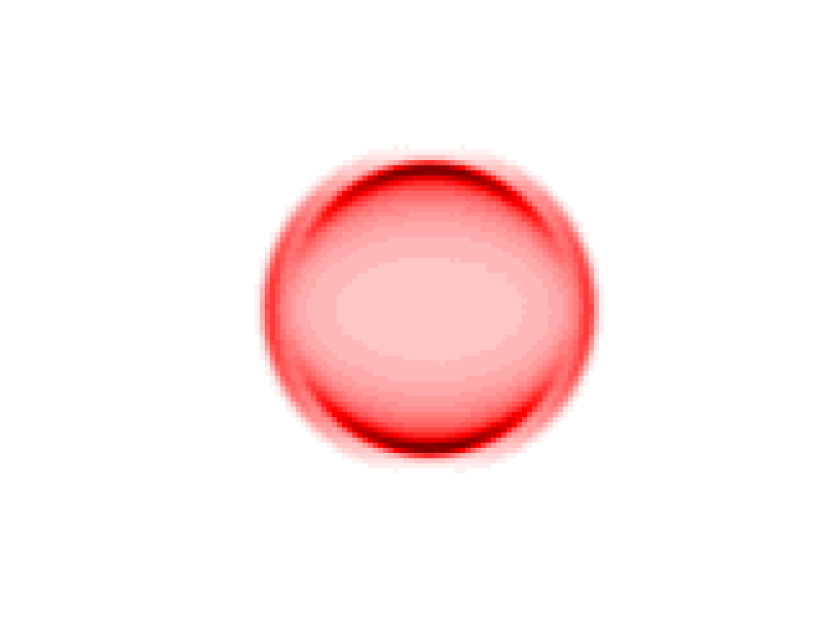

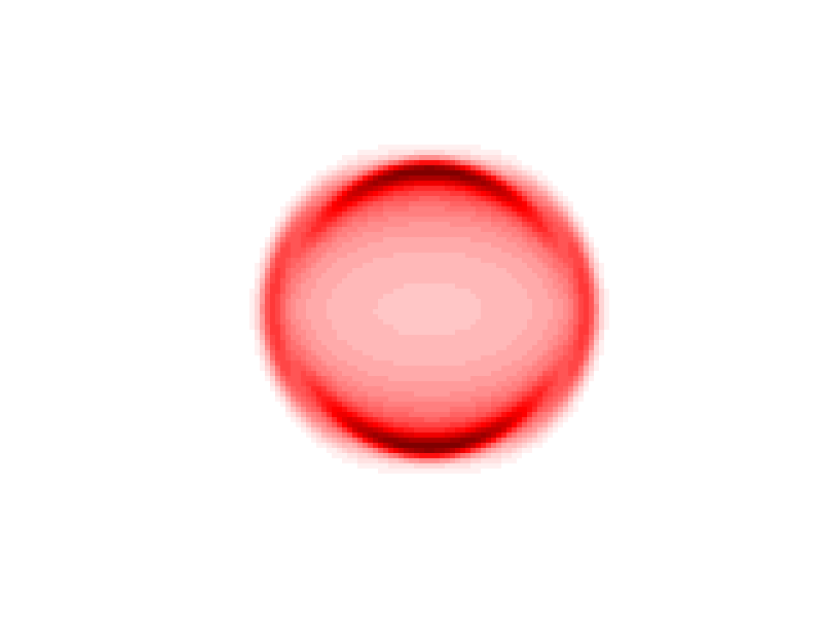

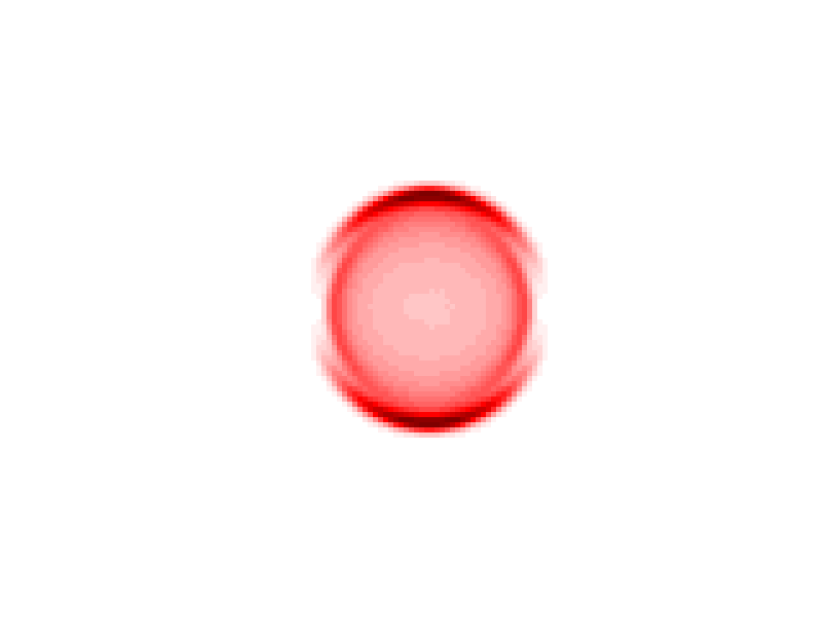

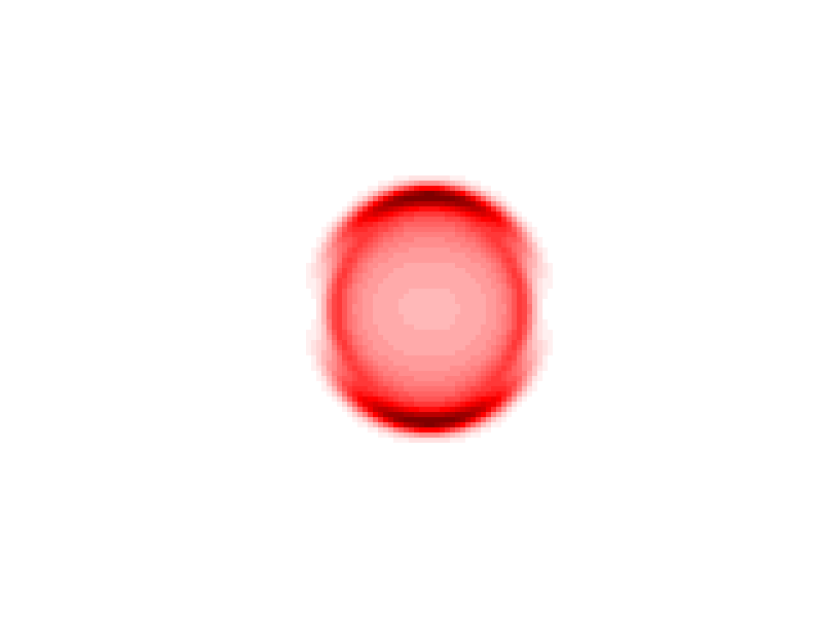

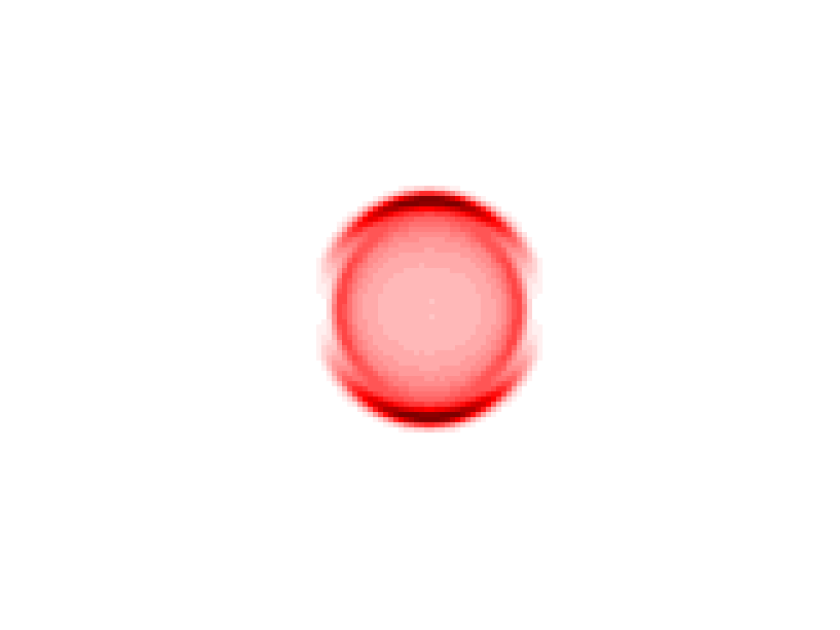

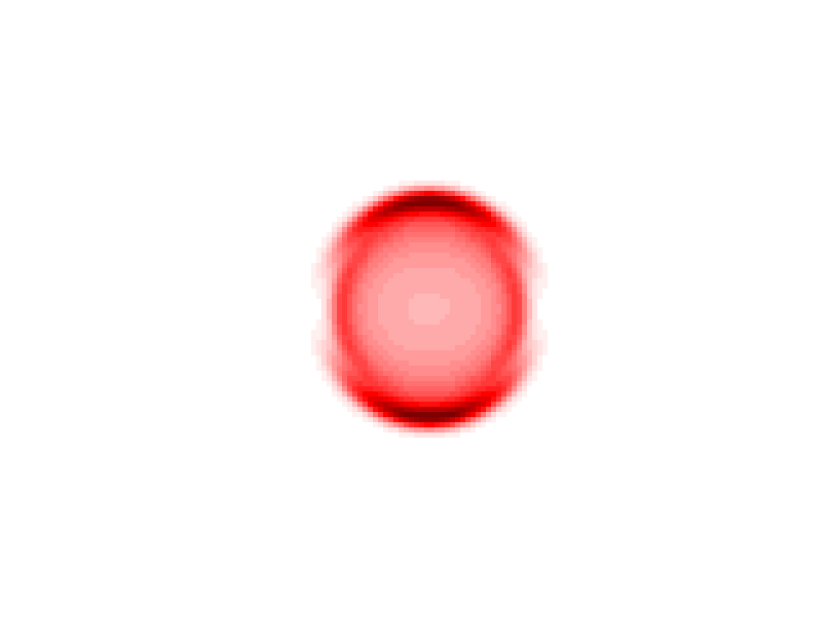

% This script was used to create a specific dataset to process through a
% trained network. 

% MPhys Research Project 2022/23
% Ross Anderson (H00295702)



% clear commands
clc
clear
close all


% set up coordinate system
x_res = 96;
y_res = 96;
x = linspace(-1, 1, x_res);
y = linspace(-1, 1, y_res);
[X, Y] = meshgrid(x, y);
R = sqrt(X.^2 + Y.^2);

cos_theta = Y./R;

P2 = (1/2)*(3*cos_theta.^2 - 1);    %second legendre polynomial
P4 = (1/8)*(35*cos_theta.^4 - 30*cos_theta.^2 + 3);     %fourth legendre polynomial
P6 = (1/16)*(231*cos_theta.^6 - 315*cos_theta.^4 - 105*cos_theta.^2 - 5);   %sixth legendre polynomial

threshold = 0.01;
N = 500;

coeffs.threshold_for_discard = threshold;
coeffs.number_of_images = N;


ring1 = cell(1, N);
ring1{1, N} = [];

ring2 = cell(1, N);
ring2{1, N} = [];

for i = 1:N

    check = 0;
    while check == 0

        %ring 1
        W1 = 0.03;  %keep constant for now
        R1 = (0.7-0.4)*rand + 0.3;
        A1 = 1;
        B21 = 2;
        I1 = A1*exp(-((R-R1)/W1).^2).*(1 + B21*P2);
        I1 = Abel(I1);
        %         I1 = I1/max(I1, [], 'all');
        %         I1 = rescale(I1);

        %ring 2
        W2 = 0.03;
        R2 = R1 + (-1)^(round(rand))*0.08;
        A2 = 1;
        B22 = -1;
        I2 = A2*exp(-((R-R2)/W2).^2).*(1 + B22*P2);
        I2 = Abel(I2);
        %         I2 = I2/max(I1, [], 'all');
        %         I2 = rescale(I2);

        ring1{i} = I1;
        coeffs_ring1.W0(i) = W1;
        coeffs_ring1.R0(i) = R1;
        coeffs_ring1.B2(i) = B21;
        coeffs_ring1.A0(i) = A1;

        ring2{i} = I2;

        coeffs_ring2.W0(i) = W2;
        coeffs_ring2.R0(i) = R2;
        coeffs_ring2.B2(i) = B22;
        coeffs_ring2.A0(i) = A2;

        I_comb_check = I1 + I2;
        I_comb_check = I_comb_check/max(I_comb_check, [], 'all');

        if any(I_comb_check(1,:) > threshold) || any(I_comb_check(:,1) > threshold) || any(I_comb_check(end,:) > threshold) || any(I_comb_check(:,end) > threshold)
            check = 0;
        else
            check = 1;
        end

    end

end


images = cell(1, N);
images{1, N} = [];

images_sampled = cell(1, N);
images_sampled{1, N} = [];

images_gaussfilt = cell(1, N);
images_gaussfilt{1, N} = [];


for i = 1:N
    I1 = ring1{i};
    I2 = ring2{i};
    I_combined = I1 + I2;
    I_combined = rescale(I_combined);
    %     showim(I_combined, 1)
    I_combined = I_combined/sum(I_combined, 'all');
    counts = I_combined*1*10^8;
    I_sampled = poissrnd(counts, height(I_combined), length(I_combined));
    while sum(isnan(I_sampled), 'all') > 0
        I_sampled = poissrnd(counts, height(I_combined), length(I_combined));
    end
    %     showim(I_sampled, 1)
    %     shading flat
    counts_in_image = sum(I_sampled,'all');
    coeffs.counts(i) = counts_in_image;
    I_gaussfilt = imgaussfilt(I_sampled, 1);    %changed from sigma = 2
    %     showim(I_gaussfilt, 1)
    %     shading flat
    I_combined = I_combined/max(I_combined, [], 'all');
    I_sampled = I_sampled/max(I_sampled, [], 'all');
    I_gaussfilt = I_gaussfilt/max(I_gaussfilt, [], 'all');
    images{i} = I_combined;
    images_sampled{i} = I_sampled;
    images_gaussfilt{i} = I_gaussfilt;

end

images_mat = cell2mat(reshape(images, 1, 1, []));
images_sampled_mat_full = cell2mat(reshape(images_sampled, 1, 1, []));
images_gaussfilt_mat_full = cell2mat(reshape(images_gaussfilt, 1, 1, []));

images_sampled_mat = images_sampled_mat_full((x_res/2+1):end, (x_res/2+1):end, :);
images_gaussfilt_mat = images_gaussfilt_mat_full((x_res/2+1):end, (x_res/2+1):end, :);


coeffs.ring1 = coeffs_ring1;
coeffs.ring2 = coeffs_ring2;

save("centroid_process", "images_sampled_mat")
save("gaussfilt_process", "images_gaussfilt_mat")
save("images", "images_mat")
save("coeffs_process", "coeffs")


for u = 1:5

    showim(images_sampled_mat_full(:, :, u), 1)
    shading flat
    showim(images_gaussfilt_mat_full(:, :, u), 1)
    shading flat

end


I_full = images_sampled_mat_full(:, :, 1);


for k = 2:10
    I_full = imadd(I_full, images_sampled_mat_full(:, :, k));
end


% showim(I_full, 1)
% shading flat
%
%
% showim(I_comb_check, 1)
% shading flat